Experiment 1 part 1

clear
load("exp1_1.mat");

load("exp1_2.mat");

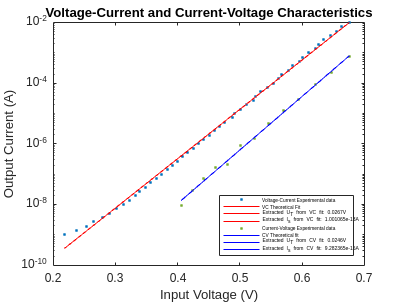

epsil=5e-3;

figure;
semilogy(V_out,exp1_1,'.',"DisplayName","Voltage-Current Experimental data");
hold on;
ylabel('Output Current (A)');
xlabel('Input Voltage (V)');
title('Voltage-Current and Current-Voltage Characteristics');
coeffs1 = polyfit(V_out, log(exp1_1), 1);
fit_line3 = exp(polyval(coeffs1, V_out));
semilogy(V_out, fit_line3, "r",'DisplayName', 'VC Theoretical Fit');
legend('Location', 'best');
U_t = 1/coeffs1(1);
I_s = exp(coeffs1(2));
ut_vis = plot(NaN, NaN,"r", 'DisplayName', sprintf('Extracted U_T from VC fit: %.4fV',U_t));
is_vis = plot(NaN, NaN, "r", 'DisplayName', sprintf('Extracted I_s from VC fit: %dA',I_s));

%FILTER OUT BAD DATA
min=0.4;
idx= exp1_2 >= min;
exp1_2 = exp1_2(idx);
I_out = I_out(idx);
semilogy(exp1_2,I_out,'.',"DisplayName","Current-Voltage Experimental data");
coeffs = polyfit(exp1_2, log(I_out), 1);
fit_line2 = exp(polyval(coeffs, exp1_2));
semilogy(exp1_2, fit_line2,"b", 'DisplayName', 'CV Theoretical fit');
legend('Location', 'best','FontSize', 4);
U_t = 1/coeffs(1);
I_s = exp(coeffs(2));
ut_vis = plot(NaN, NaN,"b", 'DisplayName', sprintf('Extracted U_T from CV fit: %.4fV',U_t));
is_vis = plot(NaN, NaN, "b", 'DisplayName', sprintf('Extracted I_s from CV fit: %dA',I_s));
hold off;
print("-dpdf","figures/experiment_1_part_1.pdf")

Experiment 1 part 2

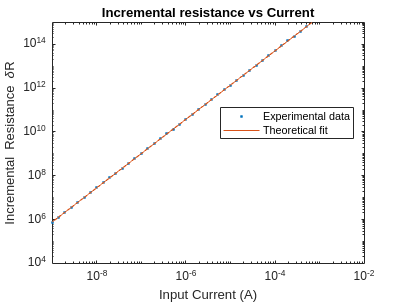

% Extract U_t and I_s

% make r_d
V_new = linspace(-0.2, 0.8, 80);
I_new = (I_s * (exp(V_new/U_t) - 1));

r_d=diff(V_new)./diff(I_new);
figure;
loglog(exp1_1,r_d(1:50),".", "DisplayName","Experimental data");
hold on;
xlim([1e-9 0.01]);
ylim([10e3 10e14]);
ylabel('Incremental Resistance \deltaR');
xlabel('Input Current (A)');
title('Incremental resistance vs Current');
legend('Location', 'best');
%fit line
coeffs4 = polyfit(log(exp1_1), log(r_d(1:50)), 1);
gradient = coeffs4(1);
y_intercept = exp(coeffs4(2));

fit_line = y_intercept * exp(gradient * log(exp1_1));
plot(exp1_1, fit_line, 'DisplayName', 'Theoretical fit');
hold off;
print("-dpdf","figures/experiment_1_part_2.pdf")

Experiment 2 part 1

clear
load("exp2_500.mat")

load("exp2_5000.mat")

load("exp2_50000.mat")

threshold = 0.6;
epsil=5e-4;

% plot all 3
figure;
plot(exp2_vin_500,exp2_500_vdiode, '.', 'DisplayName', '500\Omega');
hold on;
plot(exp2_vin_5000,exp2_5000_vdiode, '.', 'DisplayName', '5000\Omega');
plot(exp2_vin_50000,exp2_50000_vdiode, '.', 'DisplayName', '50000\Omega');
ylabel('Diode Voltage (V)');
xlabel('Input Voltage (V)');
title('Input Voltage vs Diode Voltage');
legend('Location', 'best');

%create new datasets to fit line

combinedData_500 = [exp2_500_vdiode(exp2_vin_500 < threshold)];
combinedData_5000 = [exp2_5000_vdiode(exp2_vin_5000 < threshold)];
combinedData_50000 = [exp2_50000_vdiode(exp2_vin_50000 < threshold)];
new_y = [combinedData_500, combinedData_5000, combinedData_50000];

xData_500 = [exp2_vin_500(exp2_vin_500 < threshold)];
xData_5000 = [exp2_vin_5000(exp2_vin_5000 < threshold)];
xData_50000 = [exp2_vin_50000(exp2_vin_50000 < threshold)];
new_x = [xData_500, xData_5000, xData_50000];

%fit line and plot
[f1, l1, m1, b1, n1] = linefit(new_x, new_y,epsil);
fitline1 = m1 * new_x + b1;
plot(new_x,fitline1,'DisplayName', 'Theoretical fit (V_{d}/V_{in})=0.993');
hold off;
ylim([0 0.75])
m1 %ratio is almost 1 showing that the voltages are almost the same.

m1 = 0.9983

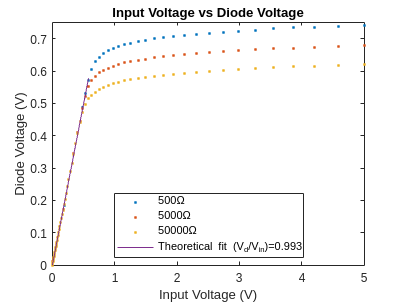

print("-dpdf","figures/experiment_2_part_1.pdf")

Experiment 2 part 2

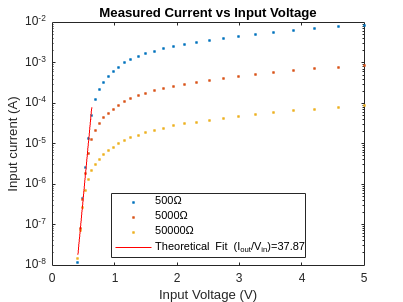

lower = 0.38;
upper = 0.64;

figure;
semilogy(exp2_vin_500(exp2_vin_500 > lower),exp2_Iout_500(exp2_vin_500 > lower), ".", 'DisplayName', "500\Omega");
hold on;
semilogy(exp2_vin_5000(exp2_vin_5000 > lower),exp2_Iout_5000(exp2_vin_5000 > lower), ".", 'DisplayName', "5000\Omega");
semilogy(exp2_vin_50000(exp2_vin_50000 > lower),exp2_Iout_50000(exp2_vin_50000 > lower), ".", 'DisplayName', "50000\Omega");
ylabel('Input current (A)');
xlabel('Input Voltage (V)');
title('Measured Current vs Input Voltage');
legend('Location', 'best');

coeffs6 = polyfit(exp2_vin_500(exp2_vin_500 > lower & exp2_vin_500 < upper), log(exp2_Iout_500(exp2_vin_500 > lower & exp2_vin_500 < upper)), 1);
fit_line6 = exp(polyval(coeffs6, exp2_vin_500(exp2_vin_500 > lower & exp2_vin_500 < upper)));
semilogy(exp2_vin_500(exp2_vin_500 > lower & exp2_vin_500 < upper), fit_line6, "r",'DisplayName', 'Theoretical Fit (I_{out}/V_{in})=37.87');
xlim([0 5]);
hold off;
print("-dpdf","figures/experiment_2_part_2.pdf")

Experiment 2 part 3

I_on=1.0011e-13*exp(0.534/0.0267)

I_on = 4.8570e-05

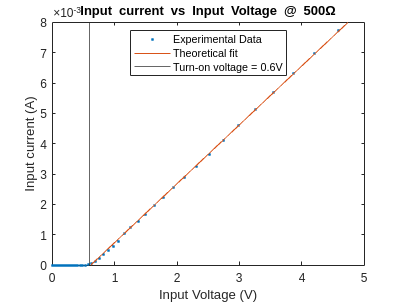

figure;
plot(exp2_vin_500,exp2_Iout_500, ".", 'DisplayName', "Experimental Data");
hold on
ylabel('Input current (A)');
xlabel('Input Voltage (V)');
title('Input current vs Input Voltage @ 500\Omega');
legend('Location', 'best');
[f2, l2, m2, b2, n2] = linefit(exp2_vin_500,exp2_Iout_500,epsil);
fitline2 = m2 * exp2_vin_500 + b2;
plot(exp2_vin_500,fitline2,'DisplayName', 'Theoretical fit');
xline(0.6,"DisplayName","Turn-on voltage = 0.6V")
hold off
ylim([0 (8*10e-4)])
print("-dpdf","figures/experiment_2_part3_500.pdf")

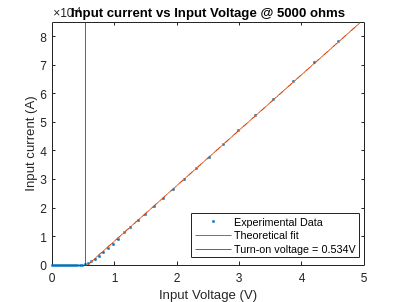


figure;
plot(exp2_vin_5000,exp2_Iout_5000, '.', 'DisplayName', "Experimental Data");
hold on
ylabel('Input current (A)');
xlabel('Input Voltage (V)');
title('Input current vs Input Voltage @ 5000 ohms');
legend('Location', 'best');
[f3, l3, m3, b3, n3] = linefit(exp2_vin_5000,exp2_Iout_5000,epsil);
fitline3 = m3 * exp2_vin_5000 + b3;
plot(exp2_vin_5000,fitline3,'DisplayName', 'Theoretical fit');
xline(0.533978,"DisplayName","Turn-on voltage = 0.534V")
hold off
ylim([0 (.85*10e-4)])
print("-dpdf","figures/experiment_2_part3_5000.pdf")

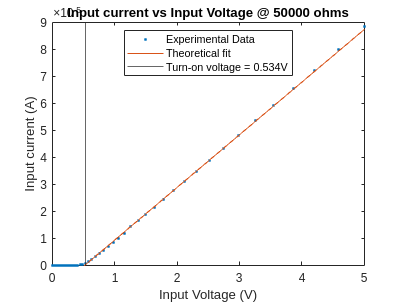


figure;
plot(exp2_vin_50000,exp2_Iout_50000, '.', 'DisplayName', "Experimental Data");
hold on
ylabel('Input current (A)');
xlabel('Input Voltage (V)');
title('Input current vs Input Voltage @ 50000 ohms');
legend('Location', 'best');
[f4, l4, m4, b4, n4] = linefit(exp2_vin_50000,exp2_Iout_50000,epsil);
fitline4 = m4 * exp2_vin_50000 + b4;
plot(exp2_vin_50000,fitline4,'DisplayName', 'Theoretical fit');
xline(0.533978,"DisplayName","Turn-on voltage = 0.534V")
hold off
ylim([0 0.00009])
print("-dpdf","figures/experiment_2_part3_50000.pdf")

Experiment 2 part 4

r_vals=[500 5000 50000];
V_ons=[0.6 0.533978 0.534];
I_ons=[4.85e-5 4.87e-5 4.82e-5];
V_on=0.0267*log(I_on/1.0011e-13)

V_on = 0.5340

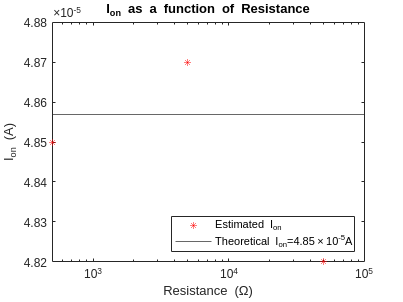


figure;
semilogx(r_vals,I_ons,"r*","DisplayName","Estimated I_{on}")
hold on;
yline(I_on,"DisplayName","Theoretical I_{on}=4.85\times10^{-5}A")
title("I_{on} as a function of Resistance")
xlabel("Resistance (\Omega)")
ylabel("I_{on} (A)")
legend('Location', 'southeast');
hold off;
ylim([4.82e-5 4.88e-5])
print("-dpdf","figures/experiment_2_part4_ion.pdf")

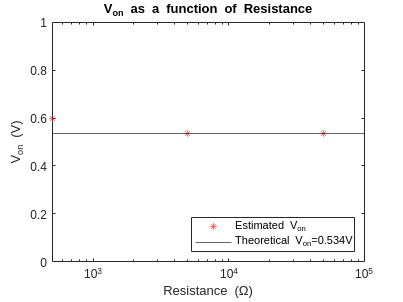



figure;
semilogx(r_vals,V_ons,"r*","DisplayName","Estimated V_{on}")
hold on;
yline(V_on,"DisplayName","Theoretical V_{on}=0.534V")
title("V_{on} as a function of Resistance")
xlabel("Resistance (\Omega)")
ylabel("V_{on} (V)")
legend('Location', 'southeast');
ylim([0 1])
hold off;
print("-dpdf","figures/experiment_2_part4_von.pdf")